# Modelling - Decision Tree & K-Nearest Neighbor

## 0) Setup

Clear workspace, load datasets with different preprocessings and convert to matrices

clear; clc; % Clear workspace
rng(1) % set seed for reproducability

% Load baseline train and test data
train = readtable('train.csv');
test = readtable('test.csv');

train = train{:,:};  % Convert to matrix
test = test{:,:};

X_train = train(:, 2:end); % Split into target and features 
y_train = train(:, 1);
X_test = test(:, 2:end);
y_test = test(:, 1);

% Load oversampled train data
X_train_SMOTE = readtable('X_train_SMOTE.csv');
y_train_SMOTE = readtable('y_train_SMOTE.csv');

X_train_SMOTE = X_train_SMOTE{:,:};
y_train_SMOTE = y_train_SMOTE{:,:};

## 1) Train / Test Baseline Models

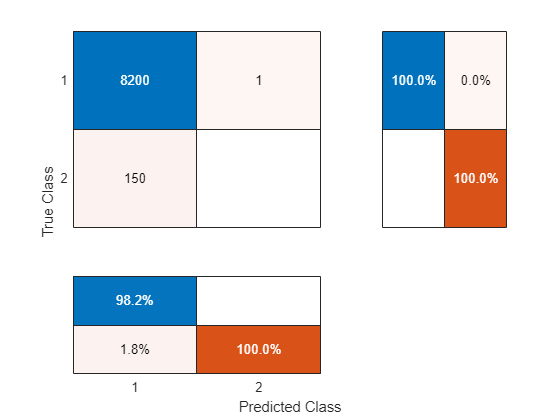

accuracy = 0.9819

precision = 0

recall = 0

specificity = 0.9999

fb = 0

% 1a) Baseline Decision Tree with default parameters
% Train
dt_base = fitctree(X_train, y_train, 'Reproducible', 1, 'MaxNumSplits', 10, 'MinLeafSize', 1);
% Evaluate baseline tree
test_model(dt_base, X_test, y_test)

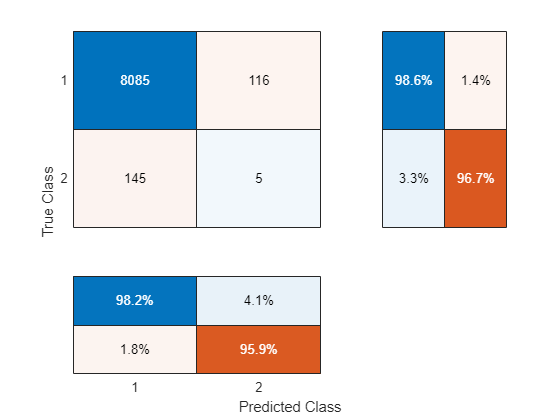

accuracy = 0.9687

precision = 0.0413

recall = 0.0333

specificity = 0.9859

fb = 0.0369

% 1b) Baseline KNN
% Train
knn_base = fitcknn(X_train, y_train, 'Standardize', 1, 'NumNeighbors', 1, 'Distance', 'euclidean', 'DistanceWeight', 'equal'); 
% Evaluate baseline knn
test_model(knn_base, X_test, y_test)

## 2) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy)

% CV SPLITS: Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train);
c = cvpartition(nrow,'KFold', 10);

% DECISION TREE: Define vars and range
MaxNumSplit = optimizableVariable('MaxNumSplit',[1, 30],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 30], 'Type', 'integer');  % default: 1
ParamsDT = [MaxNumSplit, MinLeafSize];

% KNN: Define vars and range
n = optimizableVariable('n',[1,20],'Type','integer'); % defualt: 1
dst = optimizableVariable('dst', {'euclidean', 'cosine', 'correlation'},'Type','categorical'); % default: euclidean
ParamsKNN = [n; dst];

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014878 |     0.40573 |    0.014878 |    0.014878 |           22 |            3 |
|    2 | Best   |    0.014759 |     0.20742 |    0.014759 |    0.014759 |            3 |           30 |
|    3 | Accept |    0.014819 |      0.2163 |    0.014759 |    0.014759 |            6 |            2 |
|    4 | Accept |    0.014759 |      0.2522 |    0.014759 |    0.014759 |           12 |           29 |
|    5 | Accept |    0.014819 |     0.24562 |    0.014759 |    0.014759 |           29 |           14 |
|    6 | Accept |    0.014759 |      0.2282 |    0.014759 |    0

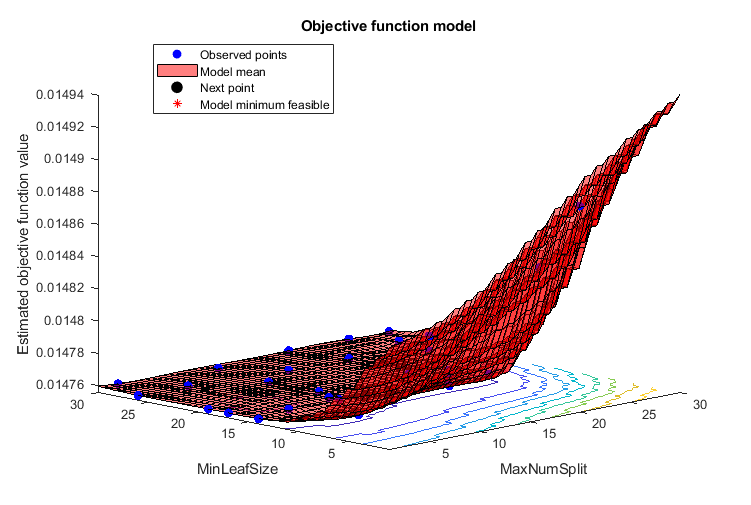

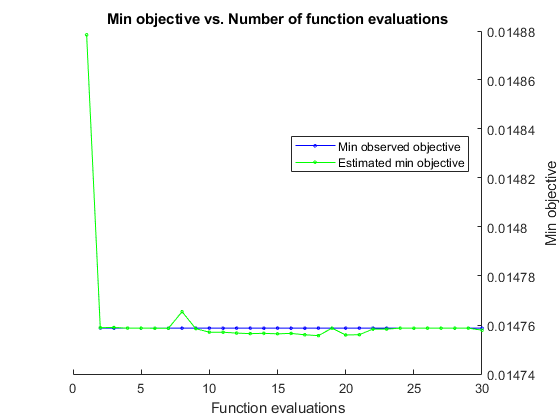


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 20.8949 seconds
Total objective function evaluation time: 6.0491

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

         3             30     

Observed objective function value = 0.014759
Estimated objective function value = 0.014759
Function evaluation time = 0.20742

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        21             15     

Estimated objective function value = 0.014758
Estimated function evaluation time = 0.21286



% 2a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train, y_train, 'CVPartition', c, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 2a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

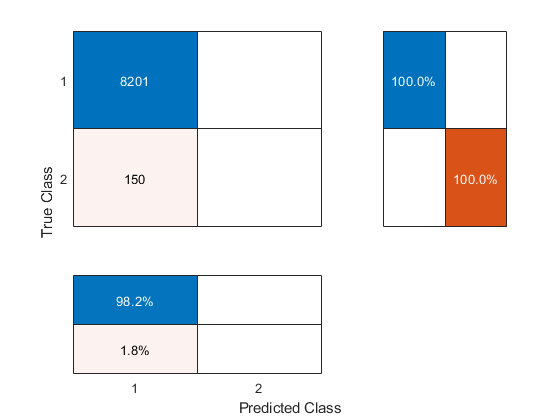

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 2a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1,...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 2a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014759 |      1.8606 |    0.014759 |    0.014759 |            7 |    euclidean |
|    2 | Accept |    0.014759 |      1.7784 |    0.014759 |    0.014759 |           13 |       cosine |
|    3 | Accept |    0.014759 |      1.8117 |    0.014759 |    0.014759 |           19 |    euclidean |
|    4 | Accept |    0.016465 |      1.7546 |    0.014759 |    0.015185 |            3 |       cosine |
|    5 | Accept |    0.014759 |      1.8149 |    0.014759 |    0.014759 |           15 |    euclidean |
|    6 | Accept |    0.014759 |      1.7759 |    0.014759 |    0

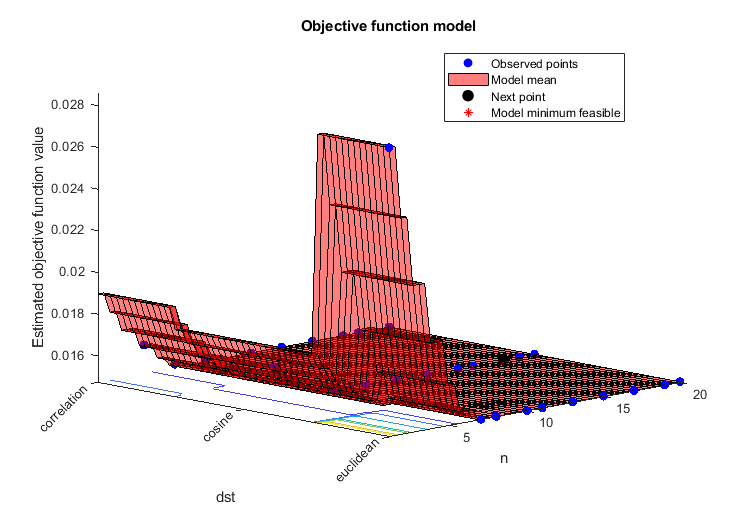

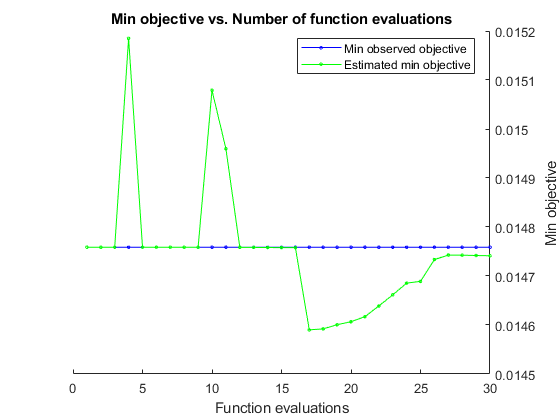


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 64.6254 seconds
Total objective function evaluation time: 53.9926

Best observed feasible point:
    n       dst   
    _    _________

    7    euclidean

Observed objective function value = 0.014759
Estimated objective function value = 0.014772
Function evaluation time = 1.8606

Best estimated feasible point (according to models):
    n       dst   
    _    _________

    8    euclidean

Estimated objective function value = 0.014741
Estimated function evaluation time = 1.8179



% 2b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', c, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst)));

% 2b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 2b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 2b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 3) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |           1 |     0.21882 |           1 |           1 |            2 |           23 |
|    2 | Accept |           1 |     0.22115 |           1 |           1 |           28 |           11 |
|    3 | Accept |           1 |      0.1959 |           1 |           1 |            7 |           21 |
|    4 | Best   |     0.99599 |     0.21858 |     0.99599 |     0.99599 |           21 |            3 |
|    5 | Accept |           1 |     0.23067 |     0.99599 |     0.99599 |           25 |           24 |
|    6 | Best   |     0.99598 |      0.2078 |     0.99598 |     

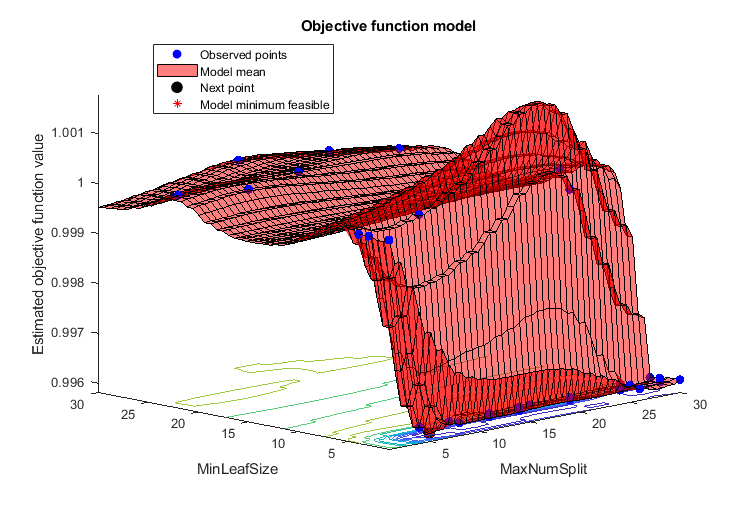

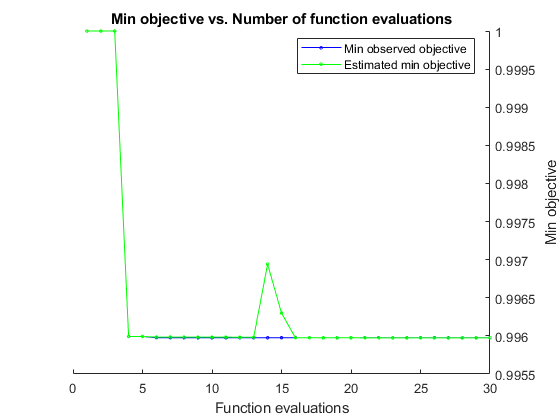


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 15.5469 seconds
Total objective function evaluation time: 6.3612

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        13              3     

Observed objective function value = 0.99598
Estimated objective function value = 0.99598
Function evaluation time = 0.2078

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

         9              3     

Estimated objective function value = 0.99597
Estimated function evaluation time = 0.2002



% 3a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c); % see helper function

% 3a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

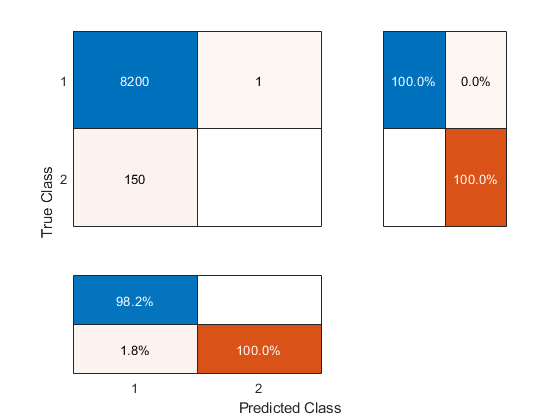

accuracy = 0.9819

precision = 0

recall = 0

specificity = 0.9999

fb = 0


% 3a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 3a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.96985 |      1.7146 |     0.96985 |     0.96985 |            1 |       cosine |
|    2 | Accept |           1 |      1.7766 |     0.96985 |     0.97137 |           19 |       cosine |
|    3 | Accept |           1 |      1.7275 |     0.96985 |     0.97862 |            5 |       cosine |
|    4 | Accept |           1 |       1.783 |     0.96985 |     0.97459 |           14 |    euclidean |
|    5 | Accept |           1 |      1.7702 |     0.96985 |     0.97371 |           17 |  correlation |
|    6 | Accept |           1 |      1.7971 |     0.96985 |     

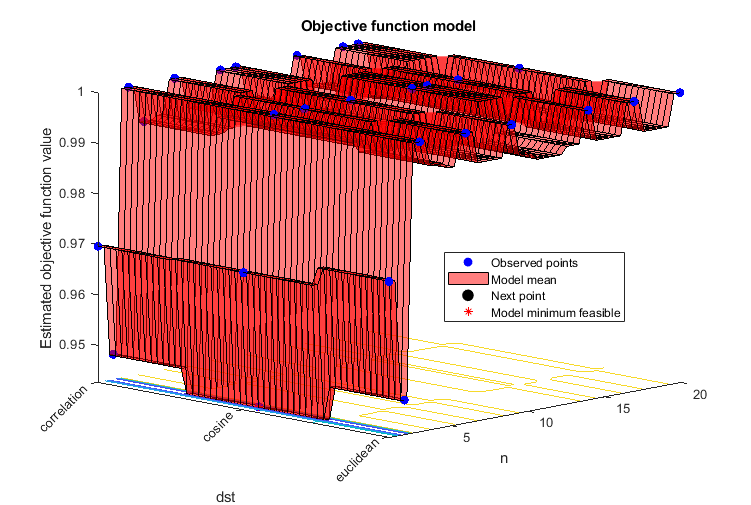

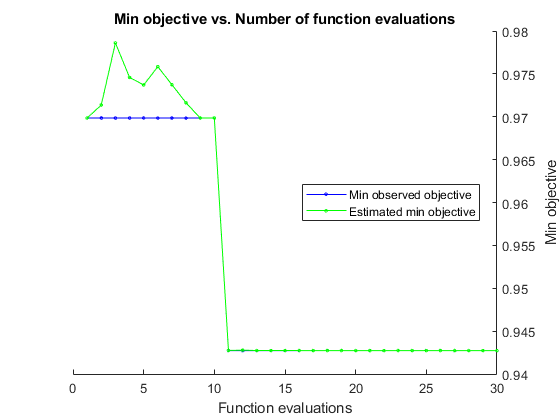


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 62.1343 seconds
Total objective function evaluation time: 52.7351

Best observed feasible point:
    n     dst  
    _    ______

    2    cosine

Observed objective function value = 0.94273
Estimated objective function value = 0.94273
Function evaluation time = 1.7196

Best estimated feasible point (according to models):
    n     dst  
    _    ______

    2    cosine

Estimated objective function value = 0.94273
Estimated function evaluation time = 1.7001



% 3b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c); % see helper function

% 3b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9819

precision = 0

recall = 0

specificity = 0.9999

fb = 0


% 3b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 3b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 4) Hyperparameter Tuning Models (CV = stratify, loss = accuracy)

% CV SPLITS (Stratified)
c_strat = cvpartition(y_train,'KFold', 10, 'Stratify', true);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014819 |     0.16704 |    0.014819 |    0.014819 |            6 |            2 |
|    2 | Best   |    0.014759 |     0.20739 |    0.014759 |    0.014759 |            8 |           18 |


|    3 | Accept |    0.014759 |     0.21701 |    0.014759 |    0.014759 |           22 |           23 |
|    4 | Accept |    0.014759 |      0.2007 |    0.014759 |    0.014758 |           14 |           19 |
|    5 | Accept |    0.014759 |     0.21676 |    0.014759 |    0.014758 |           17 |           27 |
|    6 | Accept |    0.014759 |     0.21171 |    0.014759 |    0.014758 |           25 |           11 |
|    7 | Accept |    0.015178 |     0.22023 |    0.014759 |    0.014759 |           26 |            1 |
|    8 | Accept |    0.014759 |     0.14237 |    0.014759 |    0.014759 |            3 |           14 |
|    9 | Accept |    0.014849 |      0.2246 |    0.014759 |    0.014759 |           29 |            6 |
|   10 | Accept |    0.014759 |     0.20537 |    0.014759 |    0.014759 |           10 |           12 |
|   11 | Accept |    0.014759 |     0.11514 |    0.014759 |    0.014759 |            1 |            7 |
|   12 | Accept |    0.014759 |     0.11173 |    0.014759 |    0

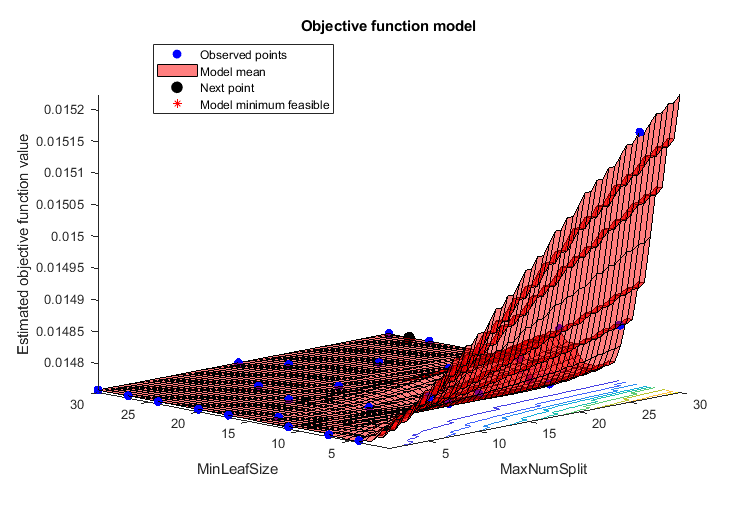

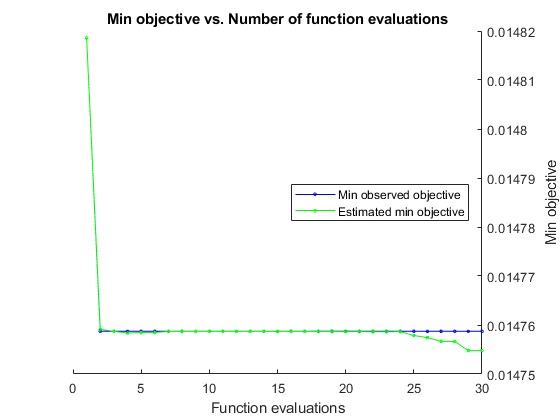


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 14.7988 seconds
Total objective function evaluation time: 5.529

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

         8             18     

Observed objective function value = 0.014759
Estimated objective function value = 0.014759
Function evaluation time = 0.20739

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        19             10     

Estimated objective function value = 0.014755
Estimated function evaluation time = 0.22168



% 4a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 4a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train, y_train, 'CVPartition', c_strat, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 4a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 4a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1,...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 4a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014759 |      1.7917 |    0.014759 |    0.014759 |           19 |  correlation |
|    2 | Accept |    0.014759 |      1.8656 |    0.014759 |    0.014759 |           15 |    euclidean |
|    3 | Accept |    0.014759 |      1.8869 |    0.014759 |    0.014759 |           16 |       cosine |
|    4 | Accept |    0.016435 |      1.6918 |    0.014759 |     0.01476 |            3 |       cosine |
|    5 | Accept |    0.014759 |      1.8573 |    0.014759 |    0.014759 |           18 |    euclidean |
|    6 | Accept |    0.014759 |      1.7623 |    0.014759 |    0

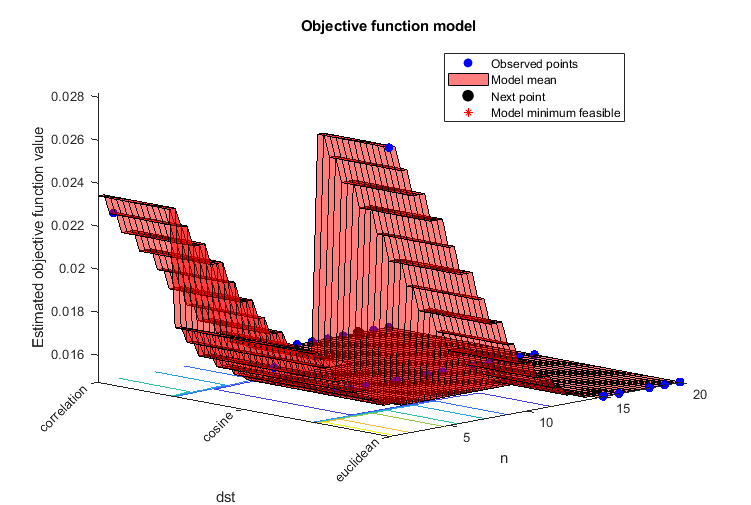

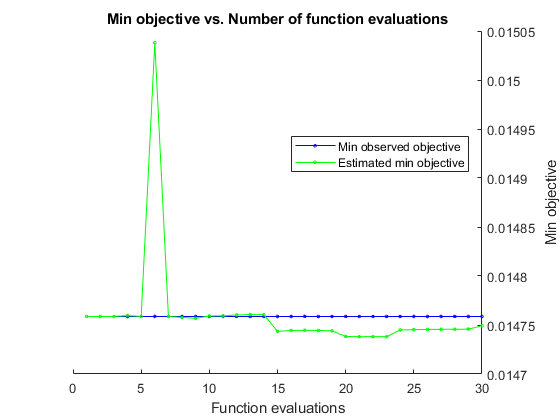


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 63.79 seconds
Total objective function evaluation time: 54.0907

Best observed feasible point:
    n         dst    
    __    ___________

    19    correlation

Observed objective function value = 0.014759
Estimated objective function value = 0.014757
Function evaluation time = 1.7917

Best estimated feasible point (according to models):
    n     dst  
    _    ______

    8    cosine

Estimated objective function value = 0.014749
Estimated function evaluation time = 1.7681



% 4b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 4b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', c_strat, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst)));

% 4b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 4b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 4b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 5) Hyperparameter Tuning Models (CV = statify, loss = f-beta)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |           1 |       0.232 |           1 |           1 |           30 |           23 |
|    2 | Accept |           1 |     0.15193 |           1 |           1 |            2 |            8 |
|    3 | Accept |           1 |     0.22987 |           1 |           1 |           29 |            9 |
|    4 | Accept |           1 |       0.252 |           1 |           1 |           18 |           30 |
|    5 | Accept |           1 |     0.21919 |           1 |           1 |           24 |            3 |
|    6 | Accept |           1 |       0.145 |           1 |     

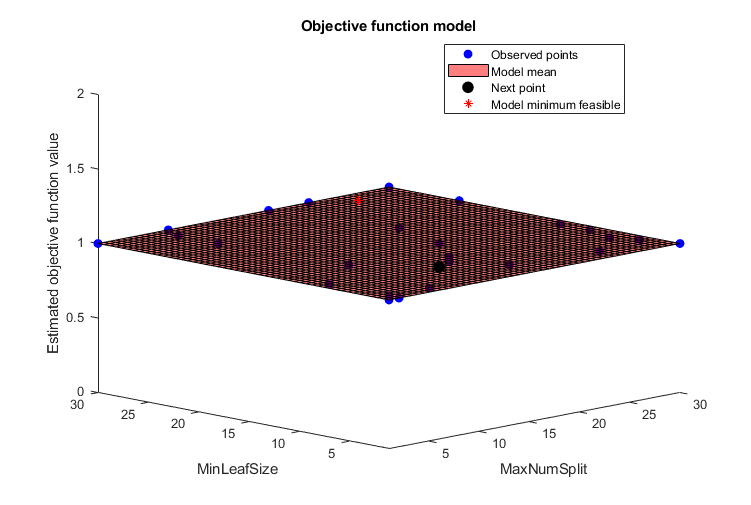

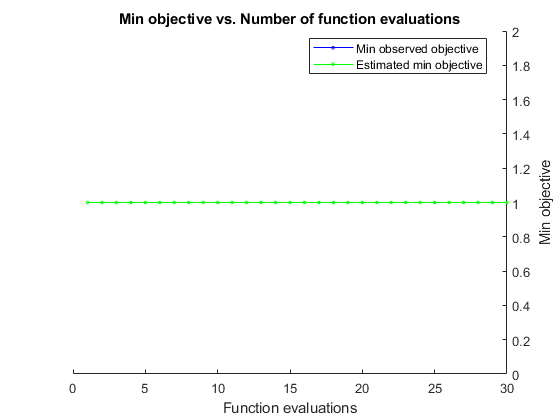


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 16.6144 seconds
Total objective function evaluation time: 5.8581

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        30             23     

Observed objective function value = 1
Estimated objective function value = 1
Function evaluation time = 0.232

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        30             23     

Estimated objective function value = 1
Estimated function evaluation time = 0.22932



% 5a) Decision Tree: Bayesian Optimization (CV = statify, loss = f-beta)
% 5a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c_strat); % see helper function

% 5a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0


% 5a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 5a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.98864 |      1.6628 |     0.98864 |     0.98864 |            4 |       cosine |
|    2 | Best   |     0.96774 |      1.6814 |     0.96774 |     0.97819 |            1 |  correlation |
|    3 | Accept |           1 |      1.8241 |     0.96774 |     0.98533 |           16 |    euclidean |
|    4 | Accept |           1 |       1.853 |     0.96774 |     0.96852 |           19 |  correlation |
|    5 | Accept |           1 |      1.7343 |     0.96774 |     0.96774 |           12 |  correlation |
|    6 | Accept |           1 |      1.7946 |     0.96774 |     

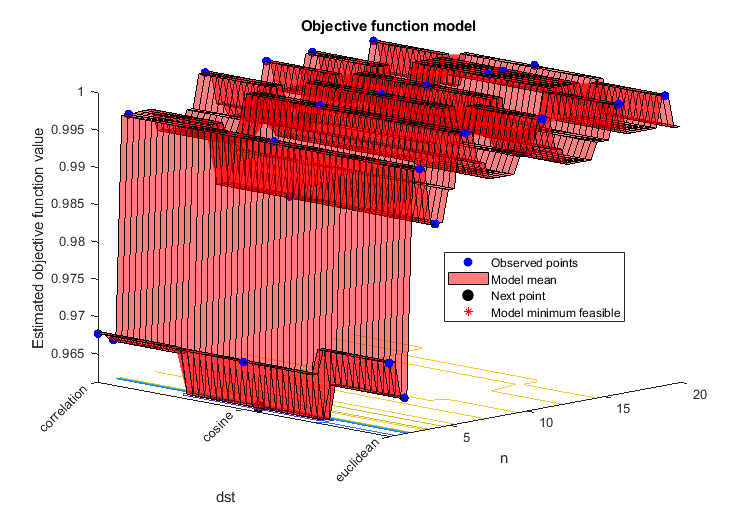

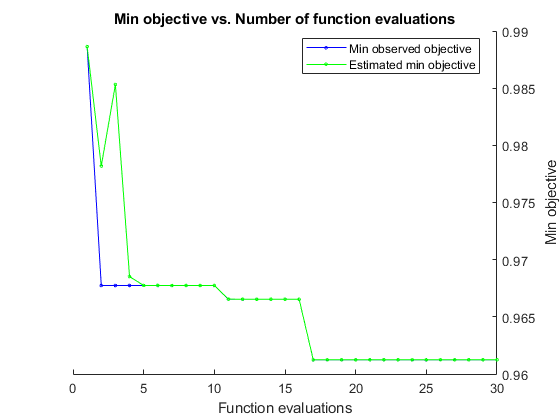


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 62.1958 seconds
Total objective function evaluation time: 52.79

Best observed feasible point:
    n     dst  
    _    ______

    2    cosine

Observed objective function value = 0.96124
Estimated objective function value = 0.96124
Function evaluation time = 1.8548

Best estimated feasible point (according to models):
    n     dst  
    _    ______

    2    cosine

Estimated objective function value = 0.96124
Estimated function evaluation time = 1.7381



% 5b) KNN: Bayesian Optimization (CV = statify, loss = f-beta)
% 5b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c_strat); % see helper function

% 5b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9819

precision = 0

recall = 0

specificity = 0.9999

fb = 0


% 5b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 5b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 6) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy, SMOTE)

% CV SPLITS SMOTE:
[nrow, ncol] = size(X_train_SMOTE);
c_SMOTE = cvpartition(nrow,'KFold', 10);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.12004 |     0.34437 |     0.12004 |     0.12004 |            6 |           26 |
|    2 | Best   |    0.090775 |     0.47884 |    0.090775 |    0.092267 |           30 |            1 |
|    3 | Accept |     0.11899 |     0.40932 |    0.090775 |    0.090778 |            9 |           17 |
|    4 | Accept |     0.10638 |     0.40281 |    0.090775 |    0.090776 |           13 |           18 |
|    5 | Accept |    0.092826 |     0.48825 |    0.090775 |    0.090776 |           19 |           10 |
|    6 | Accept |     0.13815 |     0.28046 |    0.090775 |    0

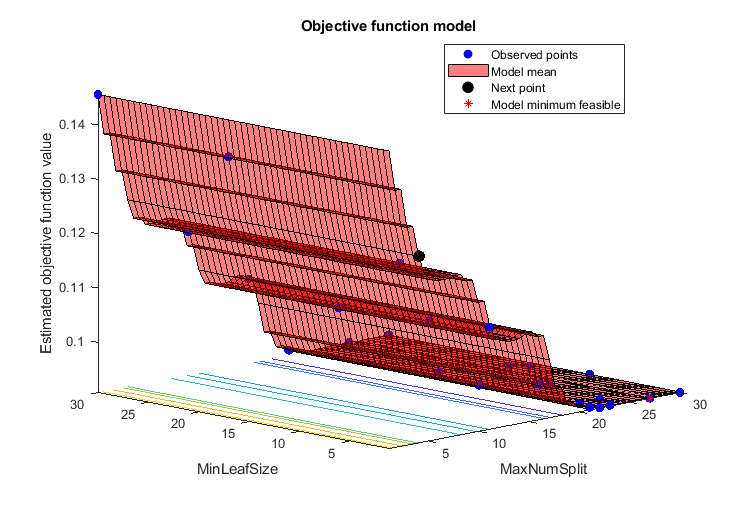

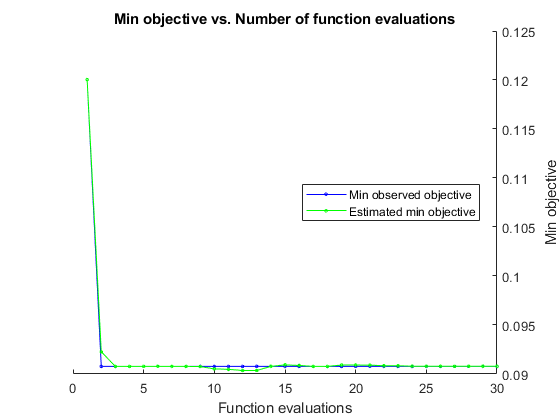


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 23.0265 seconds
Total objective function evaluation time: 13.4644

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        30              1     

Observed objective function value = 0.090775
Estimated objective function value = 0.090881
Function evaluation time = 0.47884

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        27              1     

Estimated objective function value = 0.090786
Estimated function evaluation time = 0.47642



% 6a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train_SMOTE, y_train_SMOTE, 'CVPartition', c_SMOTE, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 6a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

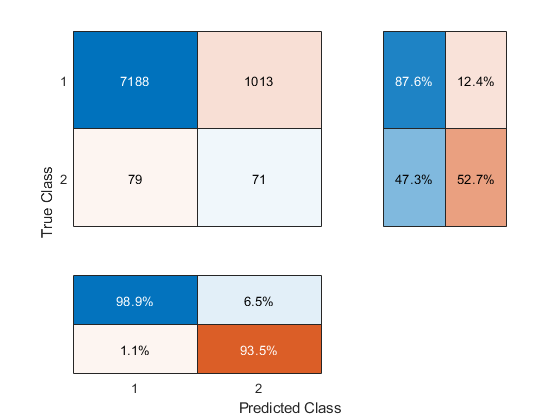

accuracy = 0.8692

precision = 0.0655

recall = 0.4733

specificity = 0.8765

fb = 0.1151

% 6a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1,...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 6a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.017031 |      6.2591 |    0.017031 |    0.017031 |           11 |  correlation |
|    2 | Accept |    0.017684 |      6.1385 |    0.017031 |    0.017357 |           12 |       cosine |
|    3 | Accept |    0.017168 |      6.1565 |    0.017031 |    0.017294 |            2 |       cosine |
|    4 | Accept |    0.019841 |      6.2121 |    0.017031 |    0.017931 |           16 |       cosine |
|    5 | Best   |     0.01264 |      5.9796 |     0.01264 |    0.012641 |            5 |  correlation |
|    6 | Accept |    0.018596 |      6.1061 |     0.01264 |    0

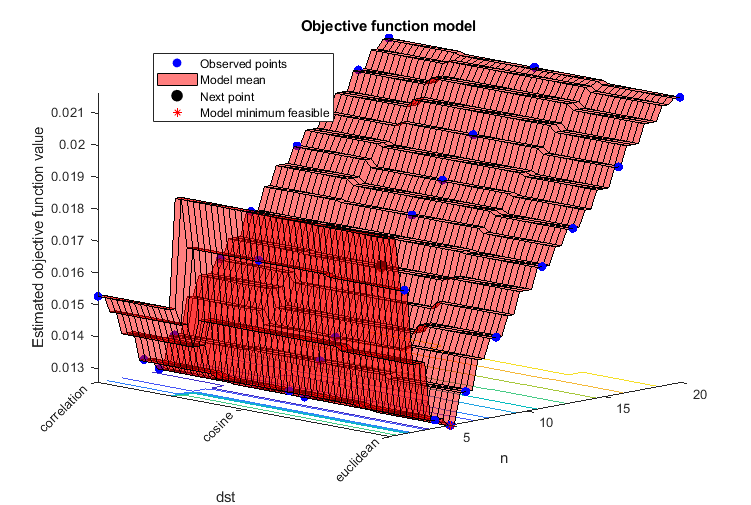

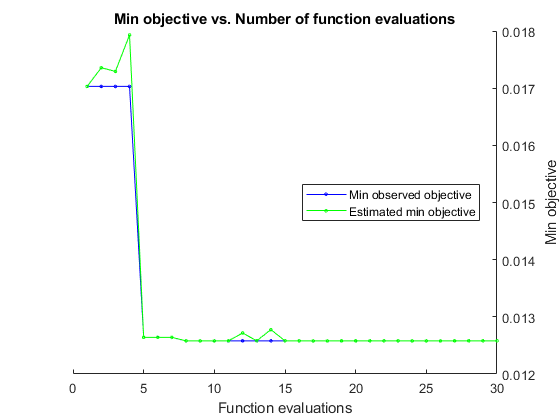


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 200.8608 seconds
Total objective function evaluation time: 190.0858

Best observed feasible point:
    n       dst   
    _    _________

    5    euclidean

Observed objective function value = 0.012579
Estimated objective function value = 0.01258
Function evaluation time = 6.4009

Best estimated feasible point (according to models):
    n       dst   
    _    _________

    5    euclidean

Estimated objective function value = 0.01258
Estimated function evaluation time = 6.4218



% 6b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, 'CVPartition', c_SMOTE, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst)));

% 6b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

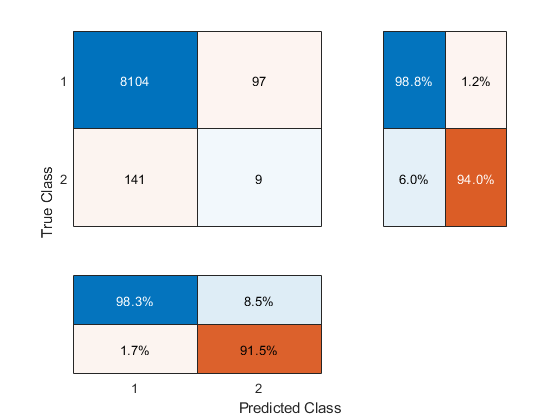

accuracy = 0.9715

precision = 0.0849

recall = 0.0600

specificity = 0.9882

fb = 0.0703

% 6b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 6b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 7) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta, SMOTE)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.12851 |     0.28905 |     0.12851 |     0.12851 |            2 |           23 |
|    2 | Best   |    0.088155 |     0.47683 |    0.088155 |    0.090165 |           28 |           11 |
|    3 | Accept |     0.11494 |     0.35383 |    0.088155 |    0.088871 |            7 |           21 |
|    4 | Accept |    0.088797 |     0.47719 |    0.088155 |    0.088153 |           21 |            3 |
|    5 | Accept |    0.088179 |      0.4974 |    0.088155 |    0.088135 |           25 |           24 |
|    6 | Accept |    0.099917 |     0.43424 |    0.088155 |    0

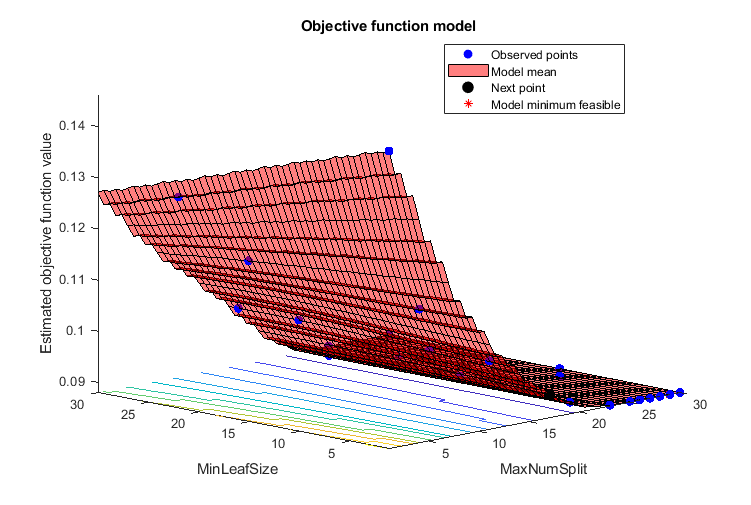

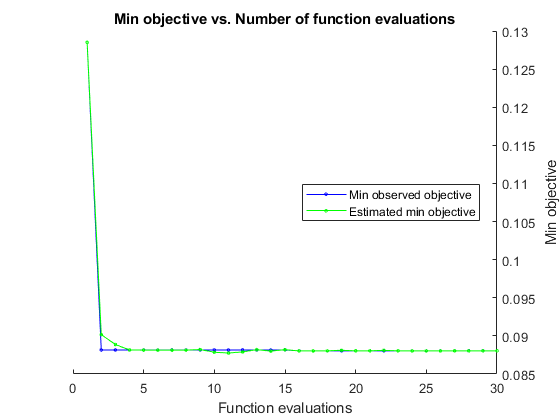


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 23.1585 seconds
Total objective function evaluation time: 13.5369

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        30              1     

Observed objective function value = 0.08804
Estimated objective function value = 0.088042
Function evaluation time = 0.47807

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        29              1     

Estimated objective function value = 0.088033
Estimated function evaluation time = 0.47462



% 7a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 7a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train_SMOTE,y_train_SMOTE, c_SMOTE); % see helper function

% 7a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.8692

precision = 0.0655

recall = 0.4733

specificity = 0.8765

fb = 0.1151


% 7a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 7a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.015247 |      6.0656 |    0.015247 |    0.015247 |            1 |       cosine |
|    2 | Accept |    0.020958 |      6.3143 |    0.015247 |    0.015752 |           19 |       cosine |
|    3 | Best   |    0.012612 |      6.1372 |    0.012612 |    0.012613 |            5 |       cosine |
|    4 | Accept |      0.0183 |      6.8427 |    0.012612 |    0.012613 |           14 |    euclidean |
|    5 | Accept |    0.020119 |      6.2376 |    0.012612 |    0.012613 |           17 |  correlation |
|    6 | Accept |      0.0156 |      6.4869 |    0.012612 |    0

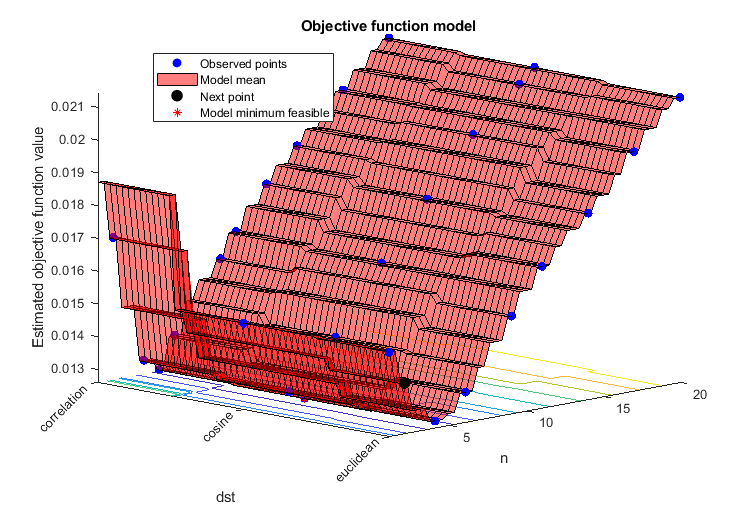

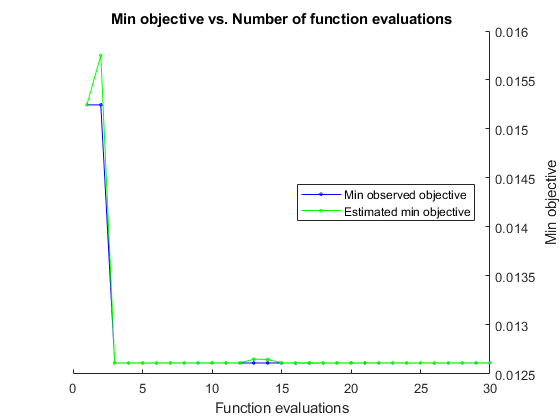


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 202.0896 seconds
Total objective function evaluation time: 190.6515

Best observed feasible point:
    n     dst  
    _    ______

    5    cosine

Observed objective function value = 0.012612
Estimated objective function value = 0.012613
Function evaluation time = 6.1372

Best estimated feasible point (according to models):
    n     dst  
    _    ______

    5    cosine

Estimated objective function value = 0.012613
Estimated function evaluation time = 6.2849



% 7b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 7b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train_SMOTE, y_train_SMOTE, c_SMOTE); % see helper function

% 7b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

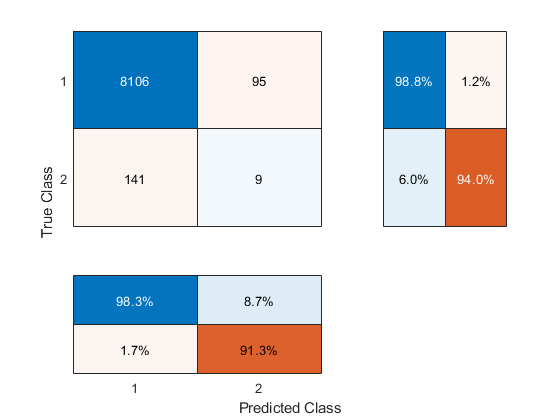

accuracy = 0.9717

precision = 0.0865

recall = 0.0600

specificity = 0.9884

fb = 0.0709


% 7b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 7b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    cm = confusionchart(cmat);
    cm.RowSummary = 'row-normalized';
    cm.ColumnSummary = 'column-normalized';
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) 
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        % Train model with selected parameters
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, 'Reproducible', 1,...
             'MaxNumSplits',params.MaxNumSplit, ...
             'MinLeafSize',params.MinLeafSize);
               
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% KNN function CV
function fb = fb_loss_knn_cv(params, X_train, y_train, cv_part)
        model = fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', cv_part, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst));
        
        % Calculate F-beta score
        y_pred = kfoldPredict(model);   
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% Evaluation metrics for binary classification
function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);

    % Statistics of interest for confusion matrix
    b = 1; % beta < 1 favours precision over recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2 * fp + fn); % (see https://en.wikipedia.org/wiki/F-score)
end
%#ok<*ASGLU,*NOPRT> 